# ME 322 System Dynamics - Laboratory Exercise 4

Author:                 Charlie Refvem

Creation Date:      5/19/25

## Symbolic Toolbox Configuration

The following preference change will make sure that the $\sigma$ values are not generated as intermediate variables when the symbolic toolbox runs.

sympref(AbbreviateOutput=false);

## Symbolic Variable Definitions

To facilitate easy setup of the equations we will first define all the symbolic variables with proper assumptions for each variable.

% State Variables
syms i_L i_R Omega_L Omega_R v_C Omega_C psi X Y        real
% Input Variables
syms V_L V_R                                            real
% Constant Parameters
syms R L k_v k_t V_DC                                   real positive
syms m_C J_C J_e r b_m w                                real positive
syms F_max k v_hat                                      real positive

## State Vector and State Equation

In this section the state vector, the input vector, and the state equations are defined.

### State Vector Definition

x = [i_L i_R Omega_L Omega_R v_C Omega_C psi X Y]';

### Input Vector Definition

u = [V_L V_R]';

### Traction Model

% Dummy Variable for Slip Velocity
v_tr = sym('v_tr', {'real'});
% Traction Function
f_tr = symfun( 0, v_tr); % ←————————————————————— ❗Traction Function Goes Here❗

### State Equations Definition

f = sym('f',[9 1]);
f(1) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(2) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(3) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(4) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(5) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(6) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(7) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(8) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
f(9) = 0; % ←———————————————————————————————————————— ❗State Equations Go Here❗
% display(f);

## Linearize the System

The nonlinear model will be linearized using Jacobian linearization. The nonlinear model is in the form $\dot{\mathbf{x}} = \mathbf{f}\left(\mathbf{x},\mathbf{u}\right)$ where the function $\mathbf{f}\left(\mathbf{x},\mathbf{u}\right)$ is nonlinear vector function that processes the system input $\mathbf{u}$ and the state vector $\mathbf{x}$ to produce the derivative of the state vector $\dot{\mathbf{x}}$. After linearization the system can be treated as a linear state-space model, but only if certain cares are taken to handle the operating point properly.

After linearization, the state equations will be in the form $\dot{\hat{\mathbf{x}}} = \hat{\mathbf{f}} + A \hat{\mathbf{x}}  + B \hat{\mathbf{u}}$ where$\hat{\mathbf{f}} = \mathbf{f}\left(\mathbf{x}_{op},\mathbf{u}_{op}\right)$ is the value of the derivative of the state vector at the operating point, $\hat{\mathbf{x}} = \mathbf{x}-\mathbf{x}_{op}$ is the value of the state vector at the operating point, and $\hat{\mathbf{u}} = \mathbf{u}-\mathbf{u}_{op}$ is the value of the input vector at the operating point.

### Determine Equilibrium Point

This section will determine the equilibrium points for the un-augmented system. That is, only the first 6 out of 9 equations will be used to determine the equilibrium point. This is required because the displacement variables in the final three elements of the state vector do not have equilibrium values when the robot is moving. It would therefore not work out to determine the equilibrium displacements associated with a specified value of $V_L$ and $V_R$.

In general, the equilibrium point can be found by setting the RHS of the state equations to zero. That is, the equilibrium point is defined by $\mathbf{u}_{op}$ and $\mathbf{x}_{op}$ such that $\mathbf{f}\left(\mathbf{x}_{op},\mathbf{u}_{op}\right) = 0$. In general systems may have between zero and infinitely many operating points. For this system, the operating points are infinite because the system has two actuators; you can think of this as solving six equations for eight variables; no matter what there will be two "free variables" left over.

Ideally we would find the equilibrium points by letting the two input variables, $V_L$ and $V_R$, which compose the input vector $\mathbf{u}$, to be the free variables. However due to particular complexities associated with solving equations in MATLAB using the symbolic toolbox, a slightly different approach will be taken.

- The equilibrium point will be determined initially with the translational velocity and angular velocity of the Romi chassis selected as free variables.

- The values of the translational and angular velocities will then be represented in terms of the input variables $V_L$ and $V_R$.

- The translational and angular velocities will then be substituted back into the equilibrium point to eliminate the translational and angular velocities in favor of $V_L$ and $V_R$. 

% First, solve for the equilibrium points of the system for an arbitrary
% forward and angular velocity of the chassis.
eq = solve(f(1:6)==0,[i_L i_R Omega_L Omega_R V_L V_R]);
% Select the input vector at equilibrium, in this case, 6 Volts on each
% motor
u_eq = [6 6]';
% Determine the forward and angular velocity of the chassis based on
% specified voltages applied to the left and right motors.

% ↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓ ❗UN-COMMENT AFTER ADDING STATE EQUATIONS❗
% eq2 = solve([eq.V_L eq.V_R] == u_eq', [v_C Omega_C]);
% ↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑ ❗UN-COMMENT AFTER ADDING STATE EQUATIONS❗


% ↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓ ❗DELETE AFTER ADDING STATE EQUATIONS❗
eq2 = struct("v_C",sym(0),"Omega_C",sym(0));
% ↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑ ❗DELETE AFTER ADDING STATE EQUATIONS❗

% Substitute the equilibrium forward and angular velocities into the
% equilibrium points to find the state vector at the selected operating point
% due to applied voltages V_L and V_R
x_op = [ subs(eq.i_L,     [v_C Omega_C], [eq2.v_C eq2.Omega_C])
         subs(eq.i_R,     [v_C Omega_C], [eq2.v_C eq2.Omega_C])
         subs(eq.Omega_L, [v_C Omega_C], [eq2.v_C eq2.Omega_C])
         subs(eq.Omega_R, [v_C Omega_C], [eq2.v_C eq2.Omega_C])
         eq2.v_C
         eq2.Omega_C                                            ];

### Determine Operating Point

Now the operating point will be found by selecting the values of the remaining three state variables when the first 6 variables are at equilibrium. For simplicity each of these variables (representing angles and displacements) are set to zero at the operating point.

x_op(7:9) = [ 0
              0
              0 ];
u_op = u_eq;
x_op = simplify(x_op);
f_op = subs(f,    [x; u], [x_op; u_op]);

### Find the Jacobian Matrices

The $A$ and $B$ matrices are found by determining two Jacobian matrices, $J_x$ and $J_u$, and then evaluating them at the selected operating point. The Jacobian matrix is a matrix of partial derivatives. The first Jacobian matrix, $J_x$, is found by differentiating the function $\mathbf{f}\left(\mathbf{x},\mathbf{u}\right)$ with respect to the state vector $\mathbf{x}$; likewise the second Jacobian matrix, $J_u$, is found by differentiating the function $\mathbf{f}\left(\mathbf{x},\mathbf{u}\right)$ with respect to the state vector $\mathbf{u}$. The $A$ matrix is found by evaluating $J_u$ at the operating point; that is, $A = \left. J_x \right|_{\mathbf{x}=\mathbf{x}_{op}, \mathbf{u}=\mathbf{u}_{op}}$; likewise, $B = \left. J_u \right|_{\mathbf{x}=\mathbf{x}_{op}, \mathbf{u}=\mathbf{u}_{op}}$.

J_x = jacobian(f,x);
A = subs(J_x, [x; u], [x_op; u_op]);
A = simplify(A);
display(A);

$$A = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_u = jacobian(f,u);
B = subs(J_u, [x; u], [x_op; u_op]);
display(B);

$$B = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

## Evaluate Matrices Numerically

IIn this section the remaining dependent parameters for the system will be computed based on the provided parameters. These include the moment of inertia of the wheel, $J_w$, the combined moment of inertia of the motor and wheel, $J_e$, the combined mass of the robot with both motors and wheels, $m_C$, the combined moment of inertia of the robot chassis and both wheels, $J_C$, and finally the maximum traction force $F_{max}$.

Load the provided parameters into a structure from the parameter file. The parameters match the following unit selection in the table below.

Table 1 - Selected Variable Units

% Load the provided parameters into a structure
p = load("lab4params.mat");
% Mom. of inertia of one motor and one wheel
p.J_e = 0; % ←——————————————————————————————————————————— ❗Parameter Goes Here❗
% Mom. of inertia of chassis and two wheels
p.J_C = 0; % ←——————————————————————————————————————————— ❗Parameter Goes Here❗
% Mass of entire system, one chassis and two wheels
p.m_C = 0; % ←——————————————————————————————————————————— ❗Parameter Goes Here❗
% Maximum traction force
p.F_max = 0; % ←————————————————————————————————————————— ❗Parameter Goes Here❗

To make substitution easier (and make the code look cleaner) an array can be built with symbolic values in the left column and numeric values in the right column. This allows substitution to be performed using code such as:

% Symbolic parameter array
sym_param = vpa([ R         p.R
                  L         p.L
                  k_v       p.k_v
                  k_t       p.k_t
                  V_DC      p.V_DC
                  m_C       p.m_C
                  J_C       p.J_C
                  J_e       p.J_e
                  r         p.r
                  b_m       p.b_m
                  w         p.w
                  F_max     p.F_max
                  k         p.k
                  v_hat     p.v_hat ], 4)

$$sym\_param = \left(\begin{array}{cc} R & 3.6\\ L & 3.2e-5\\ k_{v} & 0.158\\ k_{t} & 1.58e+8\\ V_{\mathrm{DC}} & 4.5\\ m_{C} & 0\\ J_{C} & 0\\ J_{e} & 0\\ r & 35.0\\ b_{m} & 5.64e+6\\ w & 140.0\\ F_{\max} & 0\\ k & 0.95\\ \hat{v} & 0.5 \end{array}\right)$$

### State-space Matrices

A_num = double(subs(A,sym_param(:,1),sym_param(:,2)));
B_num = double(subs(B,sym_param(:,1),sym_param(:,2)));

### Operating Point Values

x_op = double(subs(x_op, sym_param(:,1), sym_param(:,2)));
f_op = double(subs(f_op, sym_param(:,1), sym_param(:,2)));
u_op = double(subs(u_op, sym_param(:,1), sym_param(:,2))); 

## Romi Animation

### Creating the Animation

For this animation an initial dummy set of data will be used. You will need to replace this dummy data with your simulation output (once it is working). When the simulation output is working properly, the code below will look more like the example just below.

% ↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓↓ ❗REPLACE DUMMY DATA WITH SIMULATION DATA❗
t = (0:1e-3:2)';
out = struct('tout',     t, ...
             'y_nonlin', [zeros(length(t),6) pi/2+pi*t 500*cos(pi*t) 500*sin(pi*t)]);
% ↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑↑ ❗REPLACE DUMMY DATA WITH SIMULATION DATA❗

The following code is a basic template to create an animation of Romi driving on plot axes.

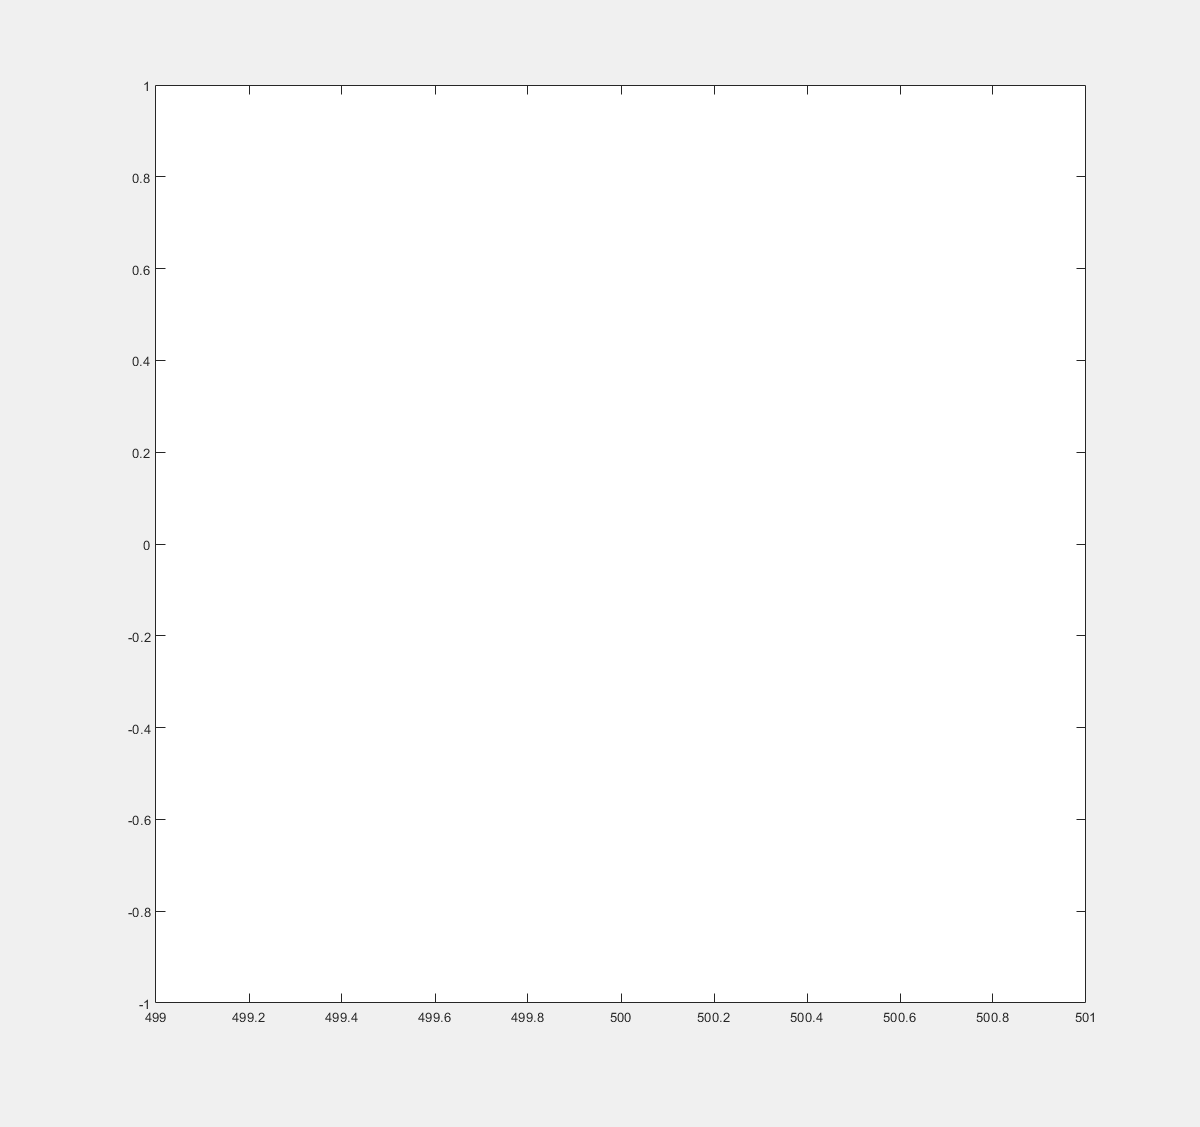

imrotate requires Image Processing Toolbox.

Error in lab4maintemplate>plot_romi_frame (line 248)
        A     = imrotate(A_b,     -rad2deg(psi)-90, "crop");

% Create Figure 9 and store a figure handle so it can be accessed again
hf9 = figure(9);
% Make the figure "pop out" of the live editor as its own window
hf9.Visible = "on";
% Set the size and position of the figure on screen. Change [1200 1200] to
% something smaller if your animation window is too big.
figsize = [1200 1200];
hf9.Position = [0 40 figsize]; 

% The framerate of the animation, used for resampling the simulation
% results at evenly spaced time steps.
fps = 30;

% The simulation time, resampled at even increments
t_an          = (0:1/fps:out.tout(end))';

% The simulation output (psi, X, and Y only) resampled at even increments
% of time
psi_nonlin_an = interp1(out.tout, out.y_nonlin(:,7), t_an);
X_nonlin_an   = interp1(out.tout, out.y_nonlin(:,8), t_an);
Y_nonlin_an   = interp1(out.tout, out.y_nonlin(:,9), t_an);

% The total number of frames of the animation
frames = length(t_an);

% An array of empty structures used to store the frames collected during
% the animation. These frames can then be used to save a .GIF file of the
% animation.
F = arrayfun(@(n) struct('cdata',[],'colormap',[]), 1:frames );

% For each frame plot the entire "scene" including Romi and the path that
% Romi has traveled.
for idx = 1:frames
    % Refocus on the figure so that plot always lands in the right spot
    figure(hf9);
    % Plot Romi's path first as a solid line, then plot Romi's image at the
    % end of the path.
    plot(X_nonlin_an(1:idx), Y_nonlin_an(1:idx), "blue")
    hold on;
    plot_romi_frame(psi_nonlin_an(idx),    X_nonlin_an(idx),    Y_nonlin_an(idx), "blue")
    hold off;
    % For Romi not to be distorted, the axes must be scaled equally.
    axis equal
    % Force MATLAB to update the plot window.
    drawnow('limitrate');
    % Capture the frame and store it in the preallocated array.
    F(idx) = getframe(hf9);
end

### Saving an Animated GIF

The code below saves the animation in a GIF.

% Specify the output file name
filename = "Romi_animation.gif";
% For each frame, save the collected frame data to the animated GIF.
for idx = 1:frames
    % Convert the RGB frame data to indexed frame data
    [im,cmap] = rgb2ind(frame2im(F(idx)),256);
    % If it's the first frame, overwrite the file
    if idx == 1
        imwrite(im,cmap,filename,"gif","LoopCount",Inf,"DelayTime",1/fps);
    % If it's not the first frame, append the frame to the file
    else
        imwrite(im,cmap,filename,"gif","WriteMode","append","DelayTime",1/fps);
    end
end

## Helper Functions

### Romi Plotting Function

The function below will plot a single frame of Romi at a specific coordinate with a specific heading. The user can also select a color for Romi (pink, red, or blue). If no color is selected the function will default to blue.

function plot_romi_frame(psi, x, y, color)

% The following variables are declared as persistent so that the function
% does not need to reload and process the image from scratch if the
% function gets called multiple times, as is expected when making an
% animation. This requires declaration of a set of variables per color, so
% that new colors of Romi may be created without overriding the image data
% from an already used color.
persistent A_p alpha_p A_r alpha_r A_b alpha_b

% Determine if a color has been selected, or if the default of blue should
% be used. The variable "nargin" is the number of input arguments. If the
% value is three it is assumed that the color input has been omitted.
if nargin == 3
    color = "blue";
end

% Depending on which color is selected, load the appropriate image file. If
% the image file for a particular color is already loaded, reuse the
% existing loaded data instead of reloading a new image. After loading the
% image, rotate the image to match the angle of Romi. If an invalid color
% has been selected throw an error as there will be no image file to load.
switch color

    % Each color will be handled separately because each color's image is
    % stored in a separate file.
    case {"pink", "Pink"}

        % If the image data is empty, that means the file hasn't been
        % loaded yet. In that case, load the data and do some pre-processing
        % to speed up future calls to the function.
        if isempty(A_p)
            % Load the correct colored image of Romi
            file = "Romi_Top_View_Pink.png";
            % Read the file, making sure to collect the alpha data which
            % represents the transparency of the pixels. That way the empty
            % space surrounding Romi within the image's bounding box is
            % transparent when plotted.
            [A_p, ~, alpha_p] = imread(file);
            % The coordinate system typically used for images has
            % coordinate axes that are positive to the right and positive
            % down; this convention for the vertical axis is opposite of
            % most conventions, like are used when generating plots. The
            % image data is flipped once loaded to compensate for the
            % vertical axis pointing up instead of down on the plot axes.
            A_p     = flip(A_p,2);
            alpha_p = flip(alpha_p,2);
        end

        % Rotate the image by the heading angle of the robot. The
        % imrotate() function, according to the documentation, rotates
        % images counter-clockwise. However, this is counter-clockwise with
        % respect to standard image axes which point to the right and down.
        % Consequently, in standard plot axes the function ends up rotating
        % images clockwise. This is easily handled by rotating by the
        % negative of the heading value. An additional rotation of 90
        % degrees is required so that the robot's coordinate frame is
        % aligned properly with the image file.
        A     = imrotate(A_p,     -rad2deg(psi)-90, "crop");
        alpha = imrotate(alpha_p, -rad2deg(psi)-90, "crop");

    % See pink case above
    case {"red", "Red", "r", "R"}

        if isempty(A_r)
            file = "Romi_Top_View_Red.png";
            [A_r, ~, alpha_r] = imread(file);
            A_r     = flip(A_r,2);
            alpha_r = flip(alpha_r,2);
        end

        A     = imrotate(A_r,     -rad2deg(psi)-90, "crop");
        alpha = imrotate(alpha_r, -rad2deg(psi)-90, "crop");

    % See pink case above
    case {"blue", "Blue", "b", "B"}

        if isempty(A_b)
            file = "Romi_Top_View_Blue.png";
            [A_b, ~, alpha_b] = imread(file);
            A_b     = flip(A_b,2);
            alpha_b = flip(alpha_b,2);
        end

        A     = imrotate(A_b,     -rad2deg(psi)-90, "crop");
        alpha = imrotate(alpha_b, -rad2deg(psi)-90, "crop");

    otherwise

        error("Invalid color selected: choose 'pink', 'red', or 'blue'")

end
% Finally, place the rotated image at appropriate scale at the right
% location on the plot axes.
image(Cdata = A, AlphaData=alpha, XData=[-70 70]+x, YData=[-70 70]+y)
end